# E4 bis

### Labelling(II)

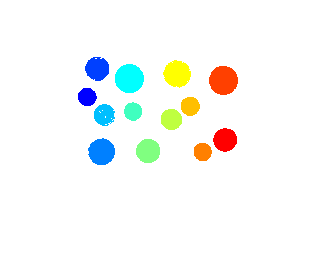

I = imread('money.tif');

level = 255*graythresh(I);
BW = I > level;

L = bwlabel(BW);

RGB = label2rgb(L);
imshow(RGB) % Visualitzar els labels

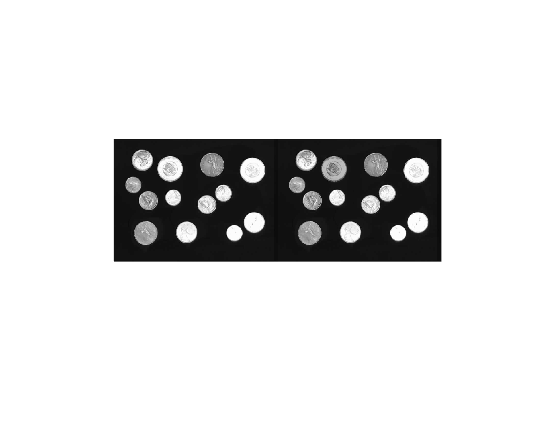



C = bwconncomp(BW);
CBW = BW;

% Atenuació d'intensitat
IC = I;
IC(C.PixelIdxList{5}) = I(C.PixelIdxList{5}) - 64;
montage({I, IC});

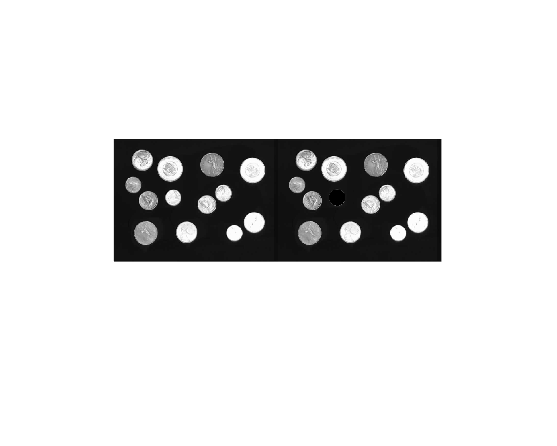


% Cerca de la moneda amb mes area = mes pixels
npixels = cellfun(@numel, C.PixelIdxList);
[npmax, pos] = min(npixels);

IC = I;
IC(C.PixelIdxList{pos}) = 0;
montage({I IC})

### Binarització local

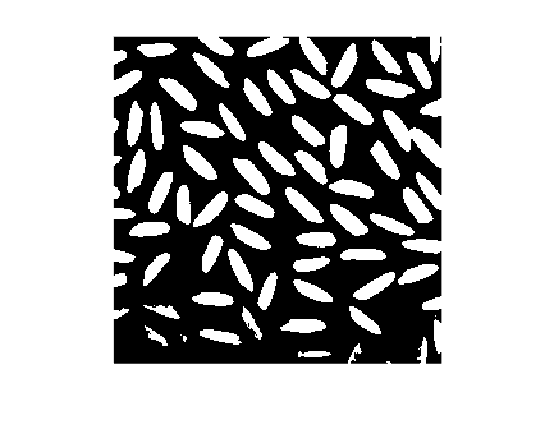

I = imread('arros.tif');
t = graythresh(I);
BW = I > 255*t;
imshow(BW);

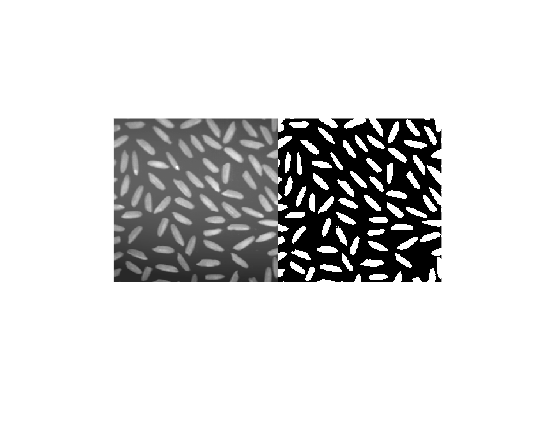


window = [30 30];
M = colfilt(I, window, "sliding", @mean);
BW = I > (M + 30);
montage({I BW})

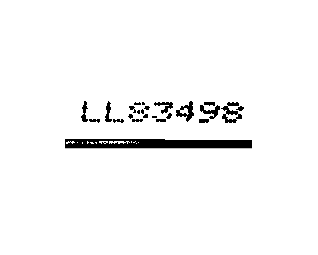

I = imread('FlatCable1.tif');
t = graythresh(I);
BW = I > 255*t;
imshow(BW);

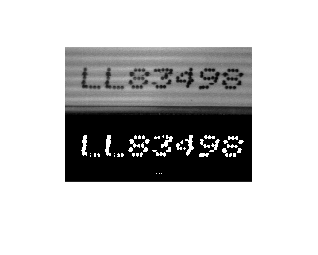


window = [5 80];
M = colfilt(I, window, "sliding", @mean);
BW = I < (M + -20);
montage({I BW})

### Exercici

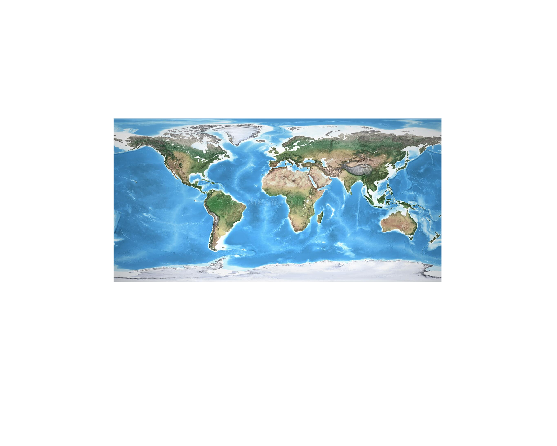

I = imread("mon2.jpg");
imshow(I);

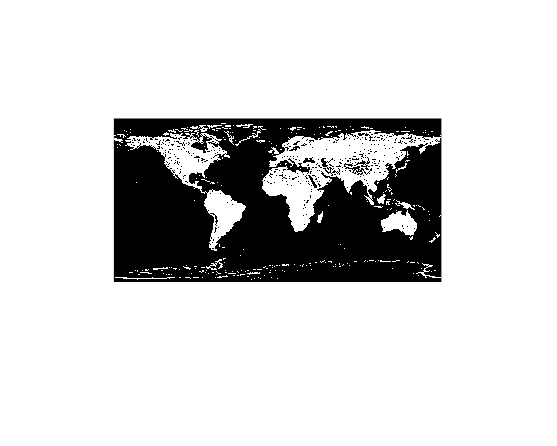


G = I(:, :, 2);

window = [20 20];
M = colfilt(G, window, "sliding", @mean);
BW = I(:, :, 3) < (M);
imshow(BW, []);